# Calculating Statistics on Matrices

Previously, you worked with matrix data to create a map of oven temperatures. Now we would like to use the map to help make decisions. For example, where should we place pizzas within the oven to ensure consistent cooking? To answer this, we'll need to calculate some statistics.

In this reading, we will apply statistical functions to the oven temperatures to find the best spots in the oven to cook pizzas. Let's start by loading the oven temperatures data.

load ovenTempsCorrected.mat ovenTemps

To visualize the temperature distribution in the oven, plot the temperatures using `surf`.

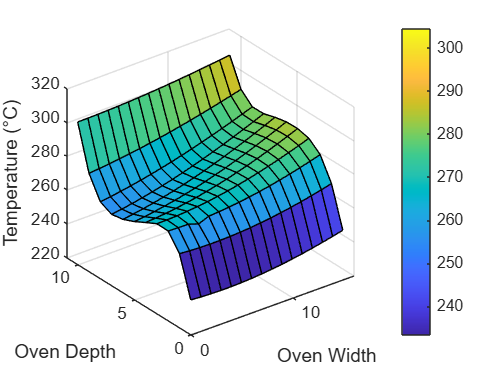

surf(ovenTemps)
xlabel("Oven Width")
ylabel("Oven Depth")
zlabel("Temperature (°C)")
colorbar

The temperature inside the oven varies between 240°C to 300°C. Considering the oven can fit 8 pizzas, it may be practical to cook 4 pizzas in the oven at one time and still have ample space to move pizzas around.

## Splitting up the oven

Therefore, let's split the oven up into four regions. Our task is to identify which quadrants have a temperature range consistently within the range for cooking pizzas, which for our pizzas is 260°C to 290°C. 

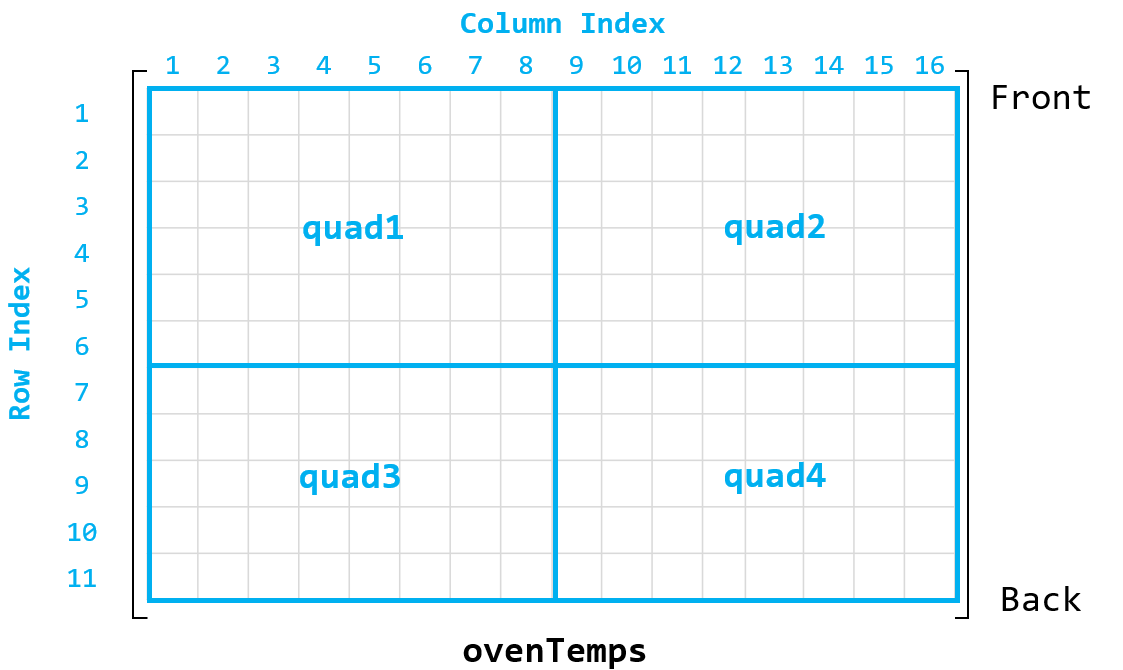

We create the quadrants by indexing our four matrices from the matrix `ovenTemps`. For example, here is the code for quadrant 1.

quad1 = ovenTemps(1:6,1:8);

Now it's your turn. Write the lines of code to create `quad2`, `quad3`, and `quad4` by indexing the columns and rows shown in the previous graphic.

quad2 = ovenTemps(1:6, 9:16);

quad2 =   234.8436  235.5738  236.4358  237.4240  238.5324  239.7548  241.0847  242.5152
  258.0394  258.7904  259.6764  260.6917  261.8299  263.0845  264.4485  265.9147
  269.1776  270.1828  271.3258  272.6002  273.9995  275.5165  277.1435  278.8729
  272.1259  273.4940  275.0008  276.6396  278.4030  280.2835  282.2729  284.3628
  271.4383  273.1435  274.9851  276.9559  279.0485  281.2547  283.5663  285.9743
  269.8202  271.7487  273.8071  275.9884  278.2851  280.6890  283.1917  285.7846


quad3 = ovenTemps(7:11, 1:8);

quad3 =   256.9025  257.7725  258.7962  259.9715  261.2959  262.7658  264.3774  266.1259
  255.6795  256.5995  257.6565  258.8489  260.1740  261.6288  263.2097  264.9123
  258.9634  259.7910  260.7345  261.7923  262.9623  264.2420  265.6282  267.1173
  271.6485  272.1987  272.8388  273.5679  274.3845  275.2866  276.2720  277.3379
  297.8246  297.8837  298.0024  298.1806  298.4176  298.7126  299.0643  299.4714


quad4 = ovenTemps(7:11, 9:16);

quad4 =   268.0062  270.0126  272.1386  274.3775  276.7220  279.1644  281.6967  284.3105
  266.7320  268.6634  270.7009  272.8381  275.0684  277.3849  279.7802  282.2466
  268.7052  270.3874  272.1590  274.0147  275.9487  277.9551  280.0276  282.1595
  278.4814  279.6988  280.9865  282.3403  283.7557  285.2281  286.7525  288.3238
  299.9319  300.4438  301.0047  301.6120  302.2628  302.9540  303.6824  304.4444


## Calculating mean and standard deviation

Let's calculate the average value within the 1st quadrant. What happens when we pass `quad1` to the `mean` function?

mean(quad1)

ans =   258.0454  258.0468  258.2147  258.1891  259.0423  259.6964  260.5061  261.4670


The function returned a vector of 8 values. That's because statistical functions like `mean` return a value for each column by default. There are 8 values because `quad1` has 8 columns. To say this another way, the calculation is applied *across* the 1st dimension, which are the rows of the matrix.

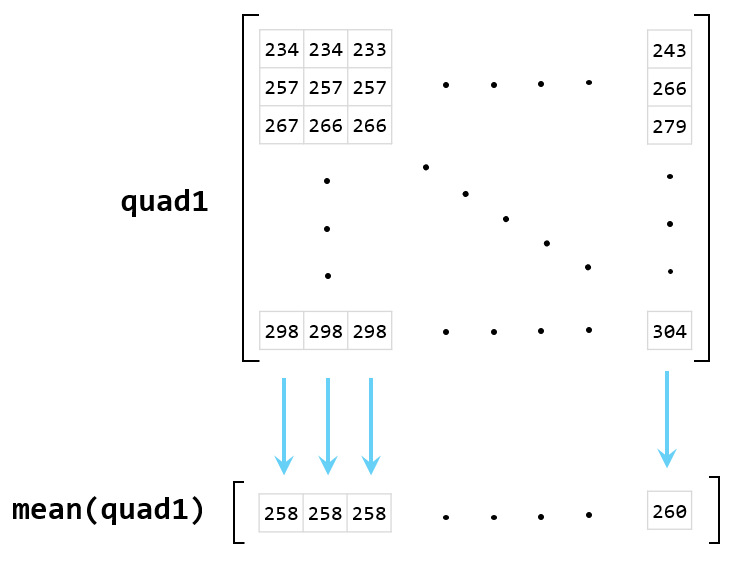

What do the values tell us? The mean values are all fairly uniform around 260°C, which is near the lower end of our range. This consistency is slightly misleading, which we can see when we plot the values. The function `plot` works similarly to statistical functions with matrices because it creates a line for each column.

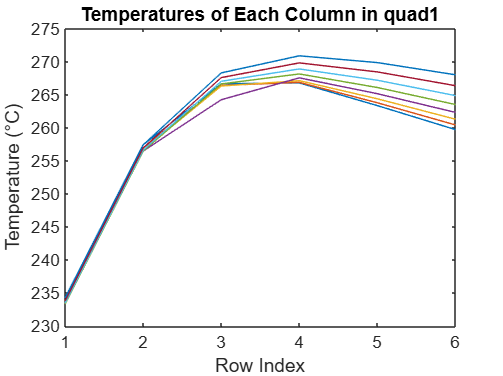

plot(quad1)
xlabel("Row Index")
ylabel("Temperature (°C)")
title("Temperatures of Each Column in quad1")

The trend for each column is similar, but the range is large. One way to see this spread is with the statistical function `std` for standard deviation (SD).

std(quad1)

ans =    12.2307   12.4589   12.7058   12.7380   13.2526   13.5505   13.8633   14.1899


A common way to report the average value is the mean ± SD. Therefore, we can report the first column of `quad1` has an average temperature of 258 ± 12 °C. This is definitely on the lower end of our desired range, but it means some parts of `quad1` would be above the required temperature of 260 °C.

What is the mean ± SD for the first column in quadrant 3? Try using the same statistical functions on quad3 to find out. Is the average temperature in quad3 higher or lower than in quad1?

mean(quad3)

ans =   268.2037  268.8491  269.6057  270.4722  271.4468  272.5271  273.7103  274.9930


std(quad3)

ans =    17.7427   17.3855   16.9938   16.5684   16.1102   15.6204   15.1003   14.5513



% mean = 268 std = 17

## Specifying a dimension

Calculating a value for each column is useful, but how do we calculate a value for each row? Or across both rows and columns? To do so, we specify the *dimension *as an input to the statistical functions. A value of 1 will apply the mean across rows, returning a value for each column (like the default). A value of 2 will apply the mean across the columns, returning a value for each row. 

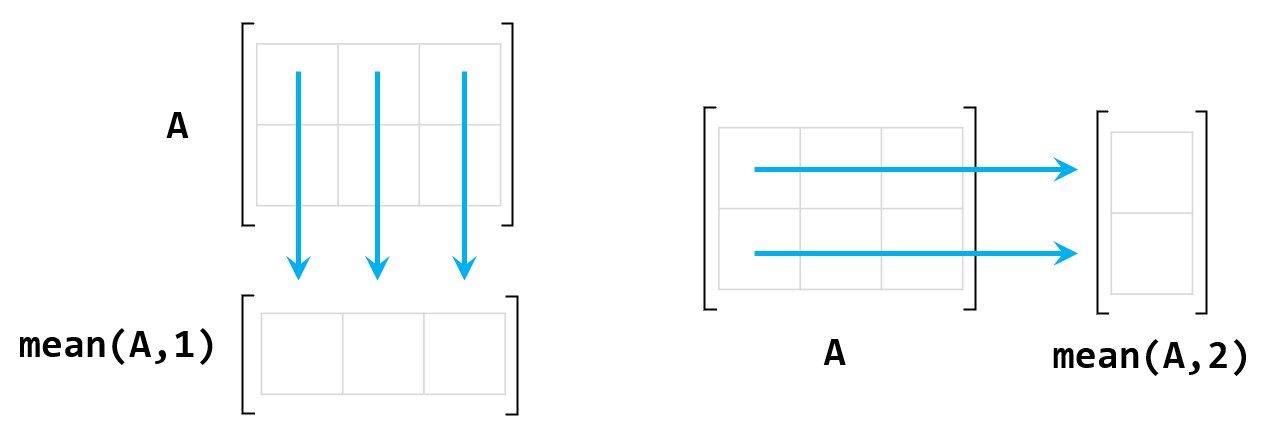

Let's calculate the mean temperature of each row in `quad1`. The function returns a vector with 6 values.

mean(quad1,2)

ans =   233.7204
  256.8780
  266.6601
  268.2738
  266.0449
  263.3286


These values have a larger range, which we can confirm by plotting each row. Since the `plot` function creates a line for each column, we transpose the matrix to invert the dimensions.

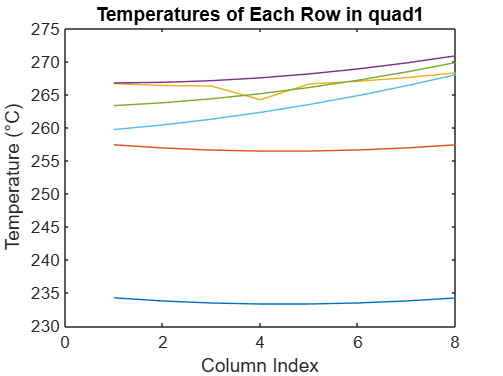

plot(quad1')
xlabel("Column Index")
ylabel("Temperature (°C)")
title("Temperatures of Each Row in quad1")

These lines are fairly flat, indicating not much variation within each row. However, there is a significant difference *between* the rows in `quad1`. The 1st row with a mean of 234 °C is the blue line at the bottom of the plot. 

Finally, we calculate the mean across both dimensions by using the string "all".

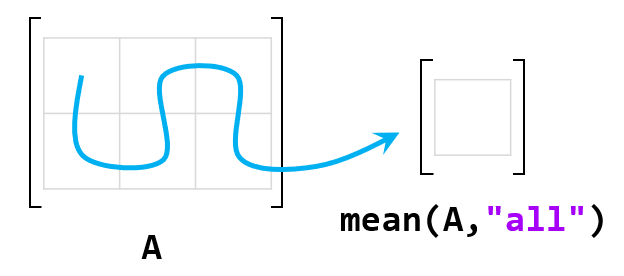

mean(quad1,"all")

ans = 259.1510

We also specify the dimension with the `std` function, but as the third input. The second input is the weighting scheme, or normalization factor, used to calculate the standard deviation. See the [documentation](https://www.mathworks.com/help/matlab/ref/std.html) for more details. The default weight is 0, which is fine for our purposes. Let's use this value to find the standard deviation of all the values in `quad1`.

std(quad1,0,"all")

ans = 12.1839

Given these values, we can report the temperature within the first quadrant is around 259 ± 12 °C.

What's the overall mean ± SD for `quad2`? Does the range overlap with the values we calculated for `quad1`?

mean(quad2,"all")

ans = 267.8275

std(quad2,0,"all")

ans = 15.0883

## Comparing quadrants

Now we have all the pieces to compare the average and spread of temperatures in each quadrant. We first calculate the values, and then we organize them by placing them in a vector.

quadrantMean = [mean(quad1,"all") mean(quad2,"all") ...
                mean(quad3,"all") mean(quad4,"all")]

quadrantMean =   259.1510  267.8275  271.2260  282.0776


Let's repeat the same calculation for the standard deviations. Create a new vector named `quadrantSpread` containing the overall standard deviation in each quadrant.

quadrantSpread = [std(quad1,0,"all") std(quad2,0,"all") ...
                std(quad3,0,"all") std(quad4,0,"all")]

quadrantSpread =    12.1839   15.0883   14.9315   11.4219


From these values, we can compare the approximate average temperatures and their spread. Replace the blank spots below with rounded values in the vector `quadrantSpread`.

- `quad1`: 259 ± __ °C

- `quad2`: 267 ± __ °C

- `quad3`: 271 ± __ °C

- `quad4`: 281 ± __ °C

roundedMean = round(quadrantMean')

roundedMean =    259
   268
   271
   282


roundedSpread = round(quadrantSpread', 1)

roundedSpread =    12.2000
   15.1000
   14.9000
   11.4000



output = compose("quad%d: %d ± %.1f °C", (1:4)', roundedMean, roundedSpread)

output = 4x1 string array
    "quad1: 259 ± 12.2 °C"
    "quad2: 268 ± 15.1 °C"
    "quad3: 271 ± 14.9 °C"
    "quad4: 282 ± 11.4 °C"


To visualize the values, let's use the function `errorbar`. We include the standard deviation values as error bar heights in order to easily compare the mean values. We also use the functions `xlim` and `xticks` to improve the appearance of the plot. The function `xlim` uses an input vector to define the x-axis limits, and the function `xticks` uses an input vector to define where the ticks are located on the x-axis.

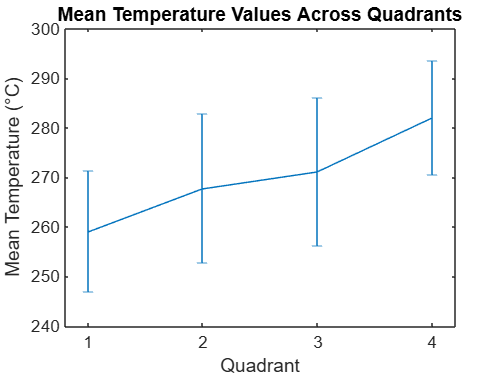

errorbar(1:4,quadrantMean,quadrantSpread)
xticks(1:4)
xlim([0.8 4.2])
xlabel("Quadrant")
ylabel("Mean Temperature (°C)")
title("Mean Temperature Values Across Quadrants")

We see from this plot that the temperatures in quadrant 4 are the most consistent within the desired range of 260 - 290 °C. The other three quadrants all have temperatures that extend well below 260 °C. Also, quadrant 4's SD is the smallest, so it would likely produce the most even cooking. We should be careful not to burn pizzas in this quadrant, though, since it's the hottest region. 

Quadrants 2 and 3 are likely still appropriate for cooking pizzas since most of their values are above 260 °C, but the pizzas will take longer to cook than in quadrant 4. Quadrant 1 has the lowest temperatures, so pizzas cooked in this quadrant will take the longest to cook. Also, the SD values are larger in quadrants 1-3, so we may need to be careful about rotating the pizzas while cooking to ensure they cooks evenly.

We've now answered our question about which quadrants are the best for cooking pizzas. We answered the question by calculating descriptive statistics with the matrix of oven temperatures. Besides the `mean` and `std` functions, there are many other basic statistics functions. Some examples are [`min`](https://www.mathworks.com/help/matlab/ref/min.html), [`mode`](https://www.mathworks.com/help/matlab/ref/mode.html), and [`median`](https://www.mathworks.com/help/matlab/ref/median.html). Check [this documentation](https://www.mathworks.com/help/matlab/descriptive-statistics.html) page to learn more about what you can do with the descriptive statistics functions.

*Copyright 2021 The MathWorks, Inc.*